# Hands-on Exercises

We will now use the GTSAM library to solve the smoothing problem as above. The file hw4_data.mat contains three variables: 

dposes - holding noisy odometry measurements, 

traj3- a rough initial estimate for robot trajectory 

poses3_gt - the actual ground truth poses

addpath(fullfile(pwd,'gtsam_toolbox'));
disp('added toolbox to path')

added toolbox to path


## 1. Load and display the initial trajectory. 

Cell array traj3 contains robot 6dof poses given as 4x4 transformation matrices (T C G in course notations). Follow the steps below to display the trajectory using GTSAM. Add your plot to your homework pdf / report.

data=importdata('hw4_data.mat');

### (a) Convert transformations to gtsam.Pose3 objects.

traj3Poses = cellfun(@(R) gtsam.Pose3(R), data.traj3);

###     (b) Store the above poses in a gtsam.Values object representing the initial estimate for robot trajectory.

trajectory = gtsam.Values;
for ii = 1:length(traj3Poses)
    trajectory.insert(gtsam.symbol('x',ii),traj3Poses(ii));
end

### (c) Use gtsam.plot3DTrajectory to display the list of poses. Include the plot in your report.

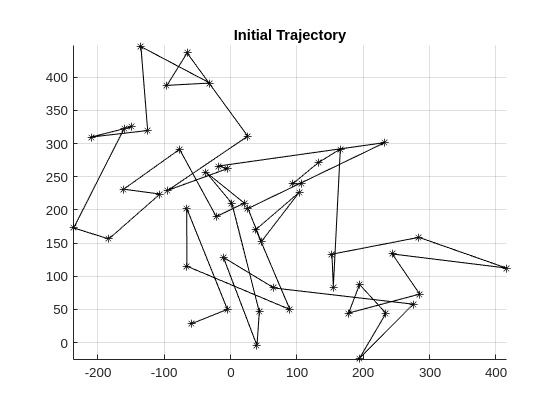

figure()
gtsam.plot3DTrajectory(trajectory, '*-k' ,200)
view([0,-1,0]); axis equal; axis tight; grid on;
title('Initial Trajectory')

### (d) Overlay in your plot the ground truth trajectory given in the variable poses3_gt (use a different color).

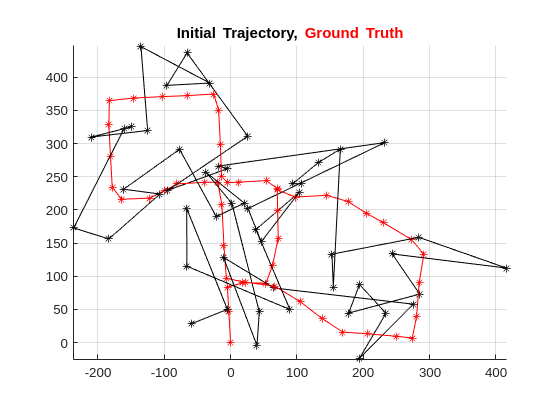

traj3Poses = cellfun(@(R) gtsam.Pose3(R), data.traj3);

gt3Poses = cellfun(@(R) gtsam.Pose3(R), data.poses3_gt);
gt = gtsam.Values;
for ii = 1:length(traj3Poses)
    gt.insert(gtsam.symbol('x',ii),gt3Poses(ii));
end

figure();
gtsam.plot3DTrajectory(trajectory, '*-k' ,200);
view([0,-1,0]); axis equal; axis tight; grid on; hold on;
gtsam.plot3DTrajectory(gt, '*-r' ,200);
title('\color{black}Initial Trajectory, \color{red}Ground Truth')

### 2. Construct factor graph. 

### (a) graph = gtsam.NonlinearFactorGraph creates a general factor graph.

graph = gtsam.NonlinearFactorGraph;

### (b) Add gtsam.BetweenFactorPose3 factors for given "measured" relative poses. 

Sr = 1e-3 * ones(3,1);
St = 0.1 * ones(3,1);
noiseModel = gtsam.noiseModel.Diagonal.Sigmas([Sr ; St ]);
zd3Poses = cellfun(@(R) gtsam.Pose3(R), data.dpose);

for ii = 1:length(zd3Poses)
    graph.add(gtsam.BetweenFactorPose3(gtsam.symbol('x',ii),...
        gtsam.symbol('x',ii+1),...
        zd3Poses(ii),...
        noiseModel));
end

### (c) Assume robot is initially located at the origin, its axes aligned with the global reference frame. Use gtsam.PriorFactorPose3 to incorporate this information into the factor graph.

Origin = gtsam.Pose3(eye(4));
graph.add(gtsam.PriorFactorPose3(gtsam.symbol('x',1),Origin,noiseModel));

### 3. Calculate and display the MAP trajectory esimate.

### (a) Create and run an optimizer.

optimizer = gtsam.LevenbergMarquardtOptimizer(graph,trajectory);
result =optimizer.optimizeSafely();

### (b) Display updated trajectory estimate.

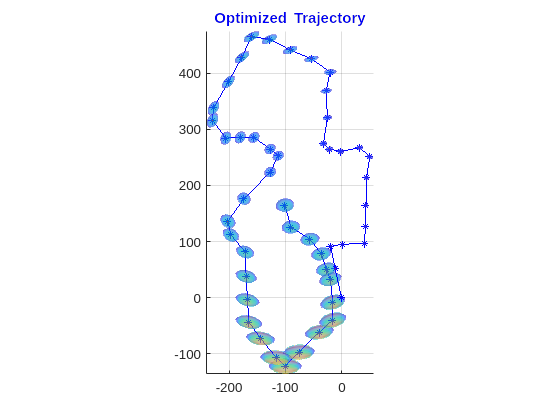

marginals = gtsam.Marginals(graph, result);

figure();
gtsam.plot3DTrajectory(result, '*-b' ,[],[],marginals)
view([0,-1,0]); axis equal; axis tight; grid on;
title('\color{blue}Optimized Trajectory');

### (c) Overlay with the ground truth as in the 1st clause.

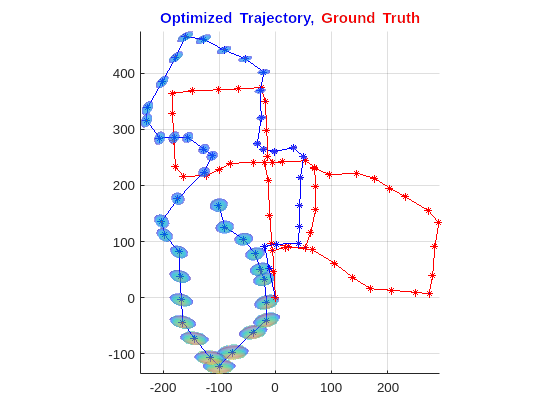

figure();
gtsam.plot3DTrajectory(result, '*-b' ,[],[],marginals)
gtsam.plot3DTrajectory(gt, '*-r' ,200);
view([0,-1,0]); axis equal; axis tight; grid on;
title('\color{blue}Optimized Trajectory, \color{red}Ground Truth')

## 4. Loop closure

R2t1=[0.330571768  0.0494690228    -0.942483486;
         0.0138000518 0.998265226     0.0572371968;
          0.943679959  -0.0319273223   0.329315626];
t_2t1_in1=[-24.1616858;
               -0.0747429903;
               275.434963];
t1 = 3;
t2 = 42;

### (a) Assuming the same noise model as before, show the estimated trajectory when incorporating this new information (as before, overlay it with ground truth).

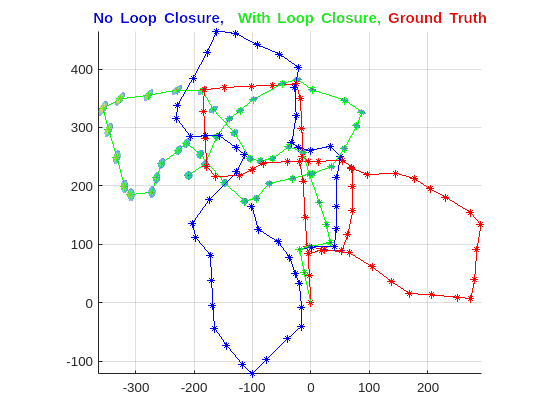

dPose = gtsam.Pose3([R2t1,t_2t1_in1; [0 0 0 1]]);
graph.add(gtsam.BetweenFactorPose3(gtsam.symbol('x',t1),...
        gtsam.symbol('x',t2),...
        dPose,...
        noiseModel));

optimizer = gtsam.LevenbergMarquardtOptimizer(graph,trajectory);
result_LC =optimizer.optimizeSafely();
marginals = gtsam.Marginals(graph, result_LC);

figure();
gtsam.plot3DTrajectory(result, '*-b');
gtsam.plot3DTrajectory(result_LC, '*-g' ,[],[],marginals);
gtsam.plot3DTrajectory(gt, '*-r' ,200);
view([0,-1,0]); axis equal; axis tight; grid on;
title('\color{blue}No Loop Closure, \color{green} With Loop Closure, \color{red}Ground Truth')

### (b) Plot the localization error in metres (location difference only - Euclidean distance) over time, for the result without and with the loop closure.

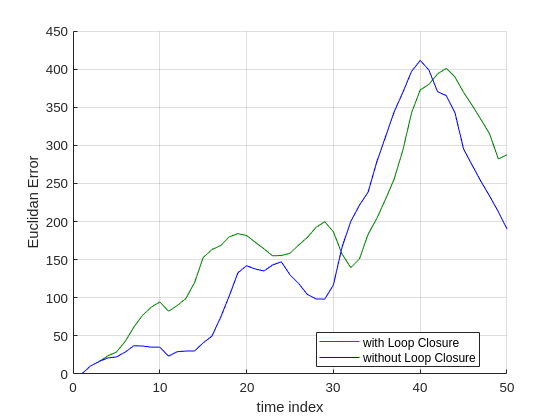

poses_gt=gtsam.utilities.extractPose3(gt);
poses_nLC=gtsam.utilities.extractPose3(result);
poses_yLC=gtsam.utilities.extractPose3(result_LC);

%extract translation, motion is almost planar on the x-z plane.
t_poses_gt = poses_gt(:,10:12);
t_poses_nLC = poses_nLC(:,10:12);
t_poses_yLC = poses_yLC(:,10:12);

err_nLC = vecnorm(t_poses_nLC - t_poses_gt,2,2);
err_yLC = vecnorm(t_poses_yLC - t_poses_gt,2,2);

fig = figure('color',[1,1,1]);
ax = axes(fig);
grid(ax,'on'); hold(ax,'on'); xlabel(ax,'time index'); ylabel(ax,'Euclidan Error');
plot(ax,err_yLC,'color',[0 0.5,0]);
plot(ax,err_nLC,'b');
legend('with Loop Closure','without Loop Closure','location','best');

### Bonus: Compute a good loop closure from poses in t9 and t50 and repeat

reminder:


$$R_1^2 =R_G^2 R_1^G ={\left(R_2^G \right)}^T R_1^G$$



$$t_{2\to 1}^2 =R_G^2 \left(t_{2\to G}^G -t_{1\to G}^G \right)={\left(R_2^G \right)}^T \left(t_{2\to G}^G -t_{1\to G}^G \right)$$


#### Reconstruct Graph

graph = gtsam.NonlinearFactorGraph;
Sr = 1e-3 * ones(3,1);
St = 0.1 * ones(3,1);
noiseModel = gtsam.noiseModel.Diagonal.Sigmas([Sr ; St ]);
zd3Poses = cellfun(@(R) gtsam.Pose3(R), data.dpose);
for ii = 1:length(zd3Poses)
    graph.add(gtsam.BetweenFactorPose3(gtsam.symbol('x',ii),...
        gtsam.symbol('x',ii+1),...
        zd3Poses(ii),...
        noiseModel));
end
Origin = gtsam.Pose3(eye(4));
graph.add(gtsam.PriorFactorPose3(gtsam.symbol('x',1),Origin,noiseModel));

#### Connect new loop closure

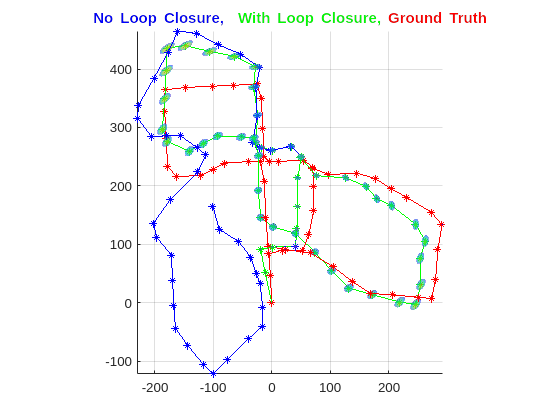


t1 = 50;
t2 = 9;

pose1 = [reshape(poses_gt(t1,:),[3,4]);[0 0 0 1]];
pose2 = [reshape(poses_gt(t2,:),[3,4]);[0 0 0 1]];
R1tG = pose1(1:3,1:3);
R2tG = pose2(1:3,1:3);
t_1tG_inG = pose1(1:3,4);
t_2tG_inG = pose2(1:3,4);

R1t2 = R2tG'*R1tG;
t_2t1_in2 = R2tG'*(t_2tG_inG-t_1tG_inG);

dPose =  gtsam.Pose3([R1t2,t_2t1_in2;[0 0 0 1]]);

graph.add(gtsam.BetweenFactorPose3(gtsam.symbol('x',t1),...
        gtsam.symbol('x',t2),...
        dPose,...
        noiseModel));

optimizer = gtsam.LevenbergMarquardtOptimizer(graph,trajectory);
result_LC =optimizer.optimizeSafely();
marginals = gtsam.Marginals(graph, result_LC);

figure();
gtsam.plot3DTrajectory(result, '*-b');
gtsam.plot3DTrajectory(result_LC, '*-g' ,[],[],marginals);
gtsam.plot3DTrajectory(gt, '*-r' ,200);
view([0,-1,0]); axis equal; axis tight; grid on;
title('\color{blue}No Loop Closure, \color{green} With Loop Closure, \color{red}Ground Truth')

#### Error Graphs for our new loop closure

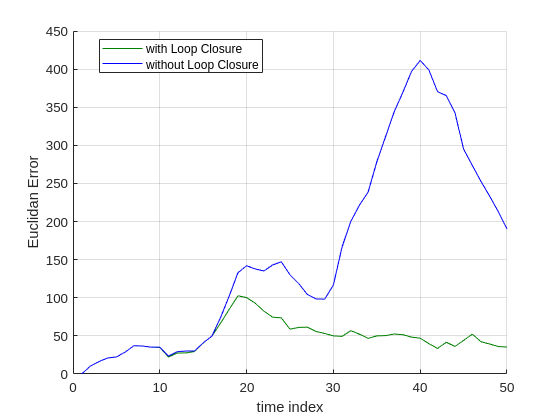

poses_gt=gtsam.utilities.extractPose3(gt);
poses_nLC=gtsam.utilities.extractPose3(result);
poses_yLC=gtsam.utilities.extractPose3(result_LC);

%extract translation, motion is almost planar on the x-z plane.
t_poses_gt = poses_gt(:,10:12);
t_poses_nLC = poses_nLC(:,10:12);
t_poses_yLC = poses_yLC(:,10:12);

err_nLC = vecnorm(t_poses_nLC - t_poses_gt,2,2);
err_yLC = vecnorm(t_poses_yLC - t_poses_gt,2,2);

fig = figure('color',[1,1,1]);
ax = axes(fig);
grid(ax,'on'); hold(ax,'on'); xlabel(ax,'time index'); ylabel(ax,'Euclidan Error');
plot(ax,err_yLC,'color',[0 0.5,0]);
plot(ax,err_nLC,'b');
legend('with Loop Closure','without Loop Closure','location','best');